clc;
clear;
close all

f0=500;
fs=10e3;
w0=2*pi*f0/fs;
n=0:300;
R=[0.8,0.9,0.99]';
w=linspace(0, pi, 512);
G=(1-R).*(1-2*R.*cos(2*w0)+R.^2).^0.5;
H1=freqz(G(1),[1, -2*R(1).*cos(2*w0), R(1).^2]);
H2=freqz(G(2),[1, -2*R(2).*cos(2*w0), R(2).^2]);
H3=freqz(G(3),[1, -2*R(3).*cos(2*w0), R(3).^2]);
H = [H1 H2 H3];

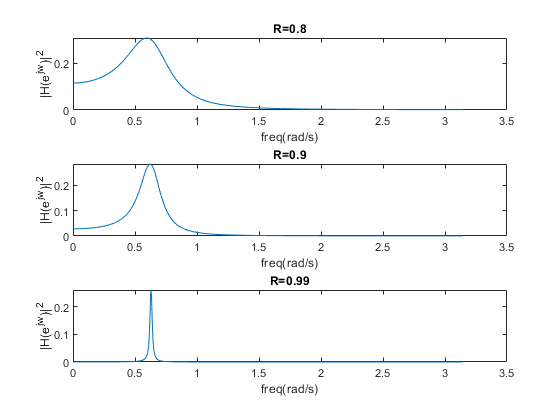

figure('name','|H_{e^jw}|^2')
for i= 1: 3
    subplot(3, 1, i)
    plot(w,abs(H(:,i).*(H(:,i))))
    title(['R=',num2str(R(i))])
    xlabel('freq(rad/s)')
    ylabel('|H(e^{jw})|^2')
end

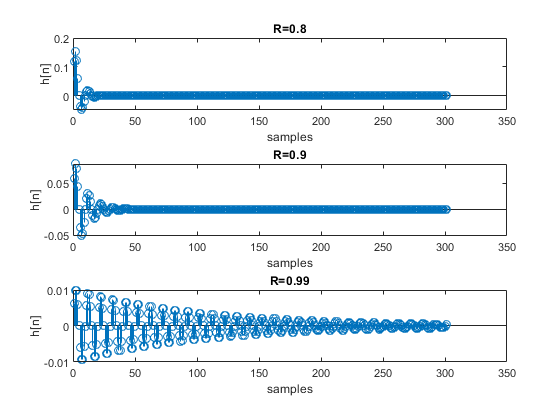

a1=-2*R.*cos(2*w0);
a2=R.^2;
x=zeros(1,301);
x(1)=1;
y_delay1=0;
y_delay2=0;
for k=1:3
y_delay1=0;
y_delay2=0;
    for i=1:301
        y(i)=G(k)*x(i)-a1(k)*y_delay1-a2(k)*y_delay2;
        y_delay2=y_delay1;
        y_delay1=y(i);
    end
Y(k,:)=y;
end
for i= 1: 3
    subplot(3, 1, i)
    stem(Y(i,:))
    title(['R=',num2str(R(i))])
    xlabel('samples')
    ylabel('h[n]')
end

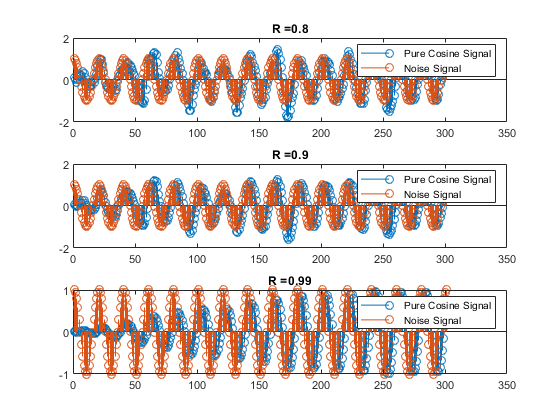

v = 1 * randn(1, 301);
n = 0:300;
x = v + cos(w0 * n);

for j = 1:3
    G = (1 - R(j)) * (1 - 2 * R(j) * cos(2 * w0) + R(j) ^ 2) ^ (0.5);
    w1 = 0;
    w2 = 0;
    y = zeros(1, 301);
    %%%
    % Here we show output by differential equation and plot it
    for i = 1:301
        y(i) = 2*R(j)*cos(w0)*w1-R(j)^2*w2+G*x(i);
        w2=w1;
        w1=y(i);
    end

    subplot(3, 1, j)
    stem(y);
    hold on;
    stem(cos(w0*n))
    title(strcat('R =', string(R(j))));
    legend('Pure Cosine Signal', 'Noise Signal');
end

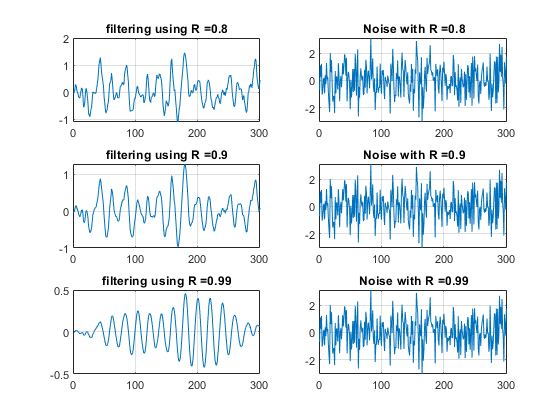


figure('Name', 'Output');
v =1*randn(1, 301);
n =0:300;
x =v;

for j = 1:3
    G=(1-R(j))*(1-2*R(j)*cos(2*w0)+R(j)^2)^(0.5);
    w1=0;
    w2=0;
    y=zeros(1,301);

    for i = 1:301
        y(i) = 2*R(j)*cos(w0)*w1-R(j)^2*w2+G*x(i);
        w2=w1;
        w1=y(i);
    end

    subplot(3,2,2*j-1)
    plot(y);
    title(strcat('filtering using R =', string(R(j))));
    hold on;
    grid on;
    subplot(3, 2, 2 * j)
    plot(v)
    title(strcat(' Noise with R =', string(R(j))));
    grid on;
end

v = 1*randn(1, 1001);
n = 0:1000;
x = v;

for j = 1:3
    G=(1-R(j))*(1-2*R(j)*cos(2*w0)+R(j)^2)^(0.5);
    w1=0;
    w2=0;
    y=zeros(1, 1001);

    for i=1:1001
        y(i) =2*R(j)*cos(w0)*w1-R(j)^2*w2+G*x(i);
        w2=w1;
        w1=y(i);
    end

    h = G/sin(w0)*R(j).^ n.*sin(w0*n+w0);
    disp(strcat('NRR for R =',string(R(j))))
    disp('Sum of H^2 signal:')
    a=sum(h.^2)
    disp(strcat('NRR for R =', string(R(j))))
    disp('Using the variance of signal:')
    va_y = var(y);
    va_x = var(x);
    a = va_y / va_x
    disp(strcat('NRR for R =', string(R(j))))
    disp('Using formula:')
    answer = G^2/(2*sin(w0)^2)*((1/(1-R(j)^2)-(cos(2*w0)-R(j)^2)/(1-2*R(j)^2*cos(2*w0)+R(j)^4)))
end

NRR for R =0.8


Sum of H^2 signal:


a = 0.1683

NRR for R =0.8


Using the variance of signal:


a = 0.1641

NRR for R =0.8


Using formula:


answer = 0.1683

NRR for R =0.9


Sum of H^2 signal:


a = 0.0975

NRR for R =0.9


Using the variance of signal:


a = 0.0987

NRR for R =0.9


Using formula:


answer = 0.0975

NRR for R =0.99


Sum of H^2 signal:


a = 0.0100

NRR for R =0.99


Using the variance of signal:


a = 0.0112

NRR for R =0.99


Using formula:


answer = 0.0100